a = dir('output_*.txt')

a = 6×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum



filenames = {a(:).name}'

filenames = 6×1 cell array
    {'output_N=11_121_iterations.txt'}
    {'output_N=13_169_iterations.txt'}
    {'output_N=15_225_iterations.txt'}
    {'output_N=20_400_iterations.txt'}
    {'output_N=25_625_iterations.txt'}
    {'output_N=30_900_iterations.txt'}



for (i = 1:length(filenames))
   currentFile = filenames{i};
   N = str2num(strtok(currentFile, 'output_N=')); 
   d = importdata(currentFile);
   numPoints(i) = mean(d(:,1)); 
   runtime(i) = mean(d(:,2)); % s
   speed(i) = mean(d(:,3)); % Mlups
   bandwidth(i) = mean(d(:,4)); % GiB/s 
end

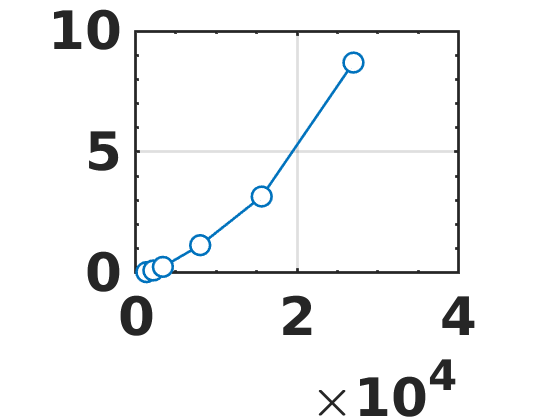

setDefaultFont('Times New Roman', 40); 
fullfig(); 
setAxisDefaults(gca); hold on; 
plot(numPoints, runtime,'-o', 'LineWidth', 2.0, 'MarkerFaceColor', 'white', 'MarkerSize', 15);